## Actual Script below

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

% Take first file (that covers 12 hours already)
trace_location = "../../traces/alibaba/2022-ms/NodeMetrics/NodeMetricsUpdate_0.csv";
[trace_header, trace_formats, trace_vartypes] = constants();
ds = tabularTextDatastore(trace_location, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedVariableNames",trace_header, ...
    "SelectedFormats", trace_formats);


clear trace_location;

prev_ds = copy(ds);
reset(prev_ds);
prev_ds.ReadSize = 10;
read(prev_ds)

ans = 10×4 table
    timestamp       node_id        cpu_utilization    memory_utilization
    _________    ______________    _______________    __________________

    33240000     {'NODE_23547'}        0.11647              0.46207     
    33240000     {'NODE_22287'}        0.34544              0.27876     
    33240000     {'NODE_21472'}        0.37031              0.22392     
    33240000     {'NODE_21294'}        0.14413               0.2092     
    33240000     {'NODE_20794'}        0.28858              0.14792     
    33240000     {'NODE_20726'}        0.11617            0.0055575     
    33240000     {'NODE_20514'}        0.19556              0.28285     
    33240000     {'NODE_20229'}        0.10382              0.17292     
    33240000     {'NODE_17912'}       0.073846              0.15501     
    33240000     {'NODE_14823'}        0.20

clear prev_ds;

### Map Reduce to create table from 1 hour of data

% gcp (in parallel) or 0 (sequential)
mapreducer(gcp);

% 1 hour as millis
max_time = 1 * 60 * 60 * 1000;

% wrap mapper function to pass variable context
mapFunc = @(a, b, c)nodemetrics_mapper(a, b, c, max_time);
% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_vartypes)], 'VariableTypes',trace_vartypes, 'VariableNames',trace_header);
reduceFunc = @(a, b, c)nodemetrics_reducer(a, b, c, empty_table);
tic
node_ds = mapreduce(ds, mapFunc, reduceFunc, 'OutputFolder', './results');

Parallel mapreduce execution on the parallel pool:
********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map   1% Reduce   0%
Map   3% Reduce   0%
Map   5% Reduce   0%
Map   7% Reduce   0%
Map   9% Reduce   0%
Map  10% Reduce   0%
Map  12% Reduce   0%
Map  14% Reduce   0%
Map  16% Reduce   0%
Map  18% Reduce   0%
Map  20% Reduce   0%
Map  21% Reduce   0%
Map  23% Reduce   0%
Map  25% Reduce   0%
Map  27% Reduce   0%
Map  29% Reduce   0%
Map  30% Reduce   0%
Map  32% Reduce   0%
Map  34% Reduce   0%
Map  36% Reduce   0%
Map  38% Reduce   0%
Map  40% Reduce   0%
Map  41% Reduce   0%
Map  43% Reduce   0%
Map  45% Reduce   0%
Map  47% Reduce   0%
Map  49% Reduce   0%
Map  50% Reduce   0%
Map  52% Reduce   0%
Map  54% Reduce   0%
Map  56% Reduce   0%
Map  58% Reduce   0%
Map  60% Reduce   0%
Map  61% Reduce   0%
Map  63% Reduce   0%
Map  65% Reduce   0%
Map  67% Reduce   0%
Map  69% Reduce   0%
Map  70% Reduce   0%
Map  72% R

toc

Elapsed time is 132.598835 seconds.


clear empty_table;
clear mapFunc;
clear reduceFunc;

### Extract node data

raw_node_data = readall(node_ds);
node_data = raw_node_data{1,2}{1};
clear raw_node_data;

### Write to CSV

writetable(node_data, "NodeMetrics.csv", "Delimiter", "\t");

### Data Inspection

node_count = height(unique(node_data.node_id));
fprintf("Node Count: %i", node_count);

Node Count: 42791

### Data insights

The CPU and memory values have been normalized by the trcae publisher between 0 and 1.

TODO: Verfiy: Is '1' = a node is fully utilized, or is it in relation to the most powerful server, who is a '1'?

at_60s = node_data(node_data.timestamp == 60000, :);

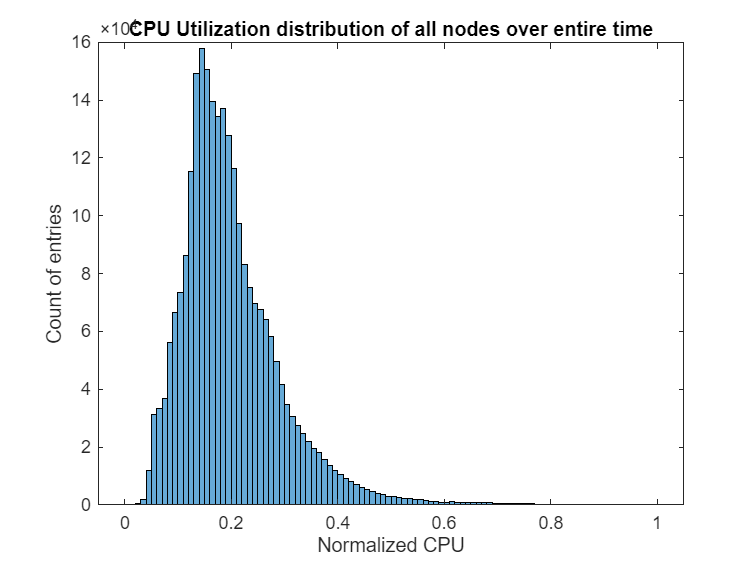

histogram(node_data.cpu_utilization, 100);
title("CPU Utilization distribution of all nodes over entire time");
ylabel("Count of entries");
xlabel("Normalized CPU");

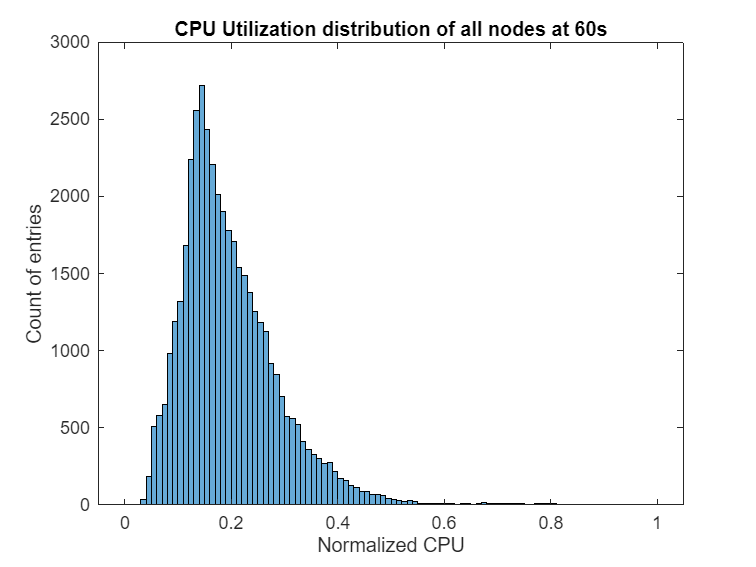


histogram(at_60s.cpu_utilization, 100);
title("CPU Utilization distribution of all nodes at 60s");
ylabel("Count of entries");
xlabel("Normalized CPU");

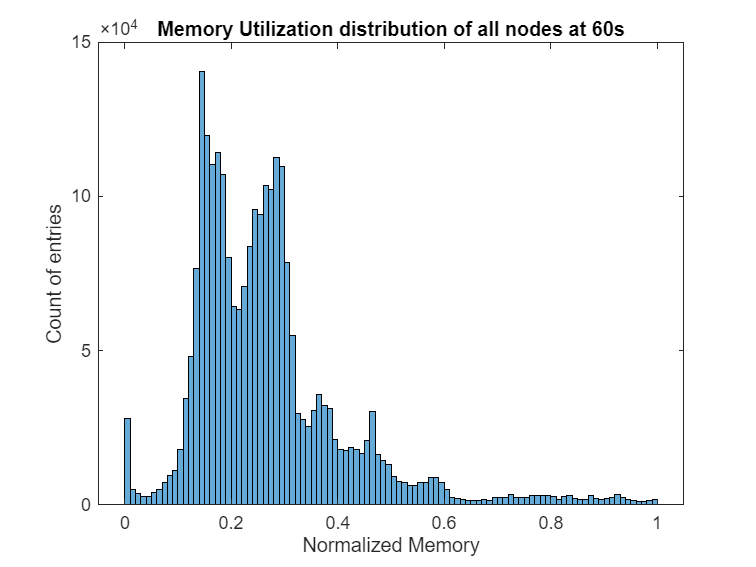

histogram(node_data.memory_utilization, 100);
title("Memory Utilization distribution of all nodes at 60s");
ylabel("Count of entries");
xlabel("Normalized Memory");

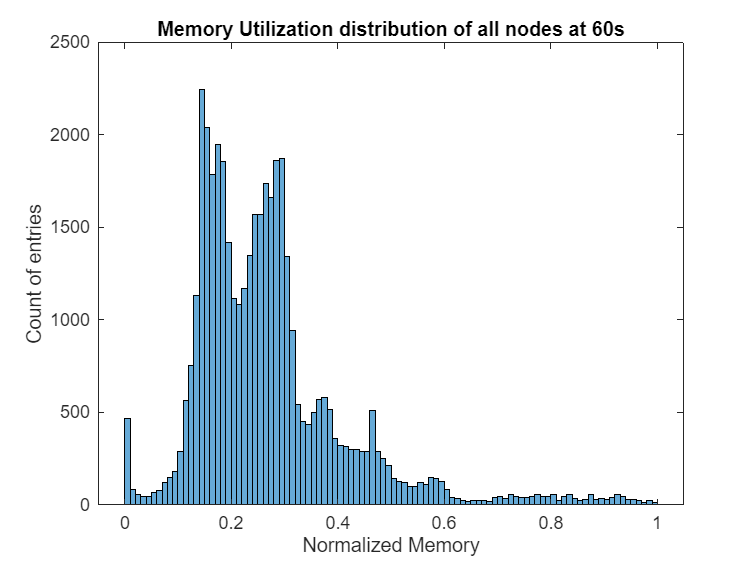


histogram(at_60s.memory_utilization, 100);
title("Memory Utilization distribution of all nodes at 60s");
ylabel("Count of entries");
xlabel("Normalized Memory");